# Melt-pool width Close loop PID Control Design 

reference:

- [https://www.mathworks.com/help/control/getstart/tune-pid-controller-to-favor-reference-tracking-or-disturbance-rejection.html](https://www.mathworks.com/help/control/getstart/tune-pid-controller-to-favor-reference-tracking-or-disturbance-rejection.html)

- [https://www.mathworks.com/help/control/ref/pidtune.html](https://www.mathworks.com/help/control/ref/pidtune.html)

After system identification shows how to design a PID controller for the plant given by: (assumed)


$$sys = \frac{1}{\left( {s + 1} \right)} \times delay$$


block diagram for feedback loop

Consider the control system of the following illustration.

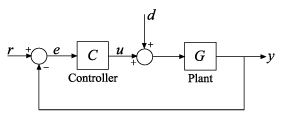

**for ****close loop****:**

- **melt-pool width (MPW)-- controlled variable, r for reference MPW, y is actual MPW.**

- **laser power (Power) -- controller output (driving force) -- *****u***** in above graph**

- **d represents disturbace**

- **G is identified ****Open Loop system Plant**** transfer function from previous section.**

[SISO Feedback Loop](https://www.mathworks.com/help/control/ref/connect.html) (Single Input- Single Output)

Create an aggregate model of the following block diagram from `r` to `y`.

%C = pid(2,1) % specifiy P and I gain for PID controller
%C.u = 'e'
%C.y = 'u'
%G = zpk([],[-1,-1],1)
%G.u = 'u'  
%G.y = 'y'
%Sum = sumblk('e = r - y')
%T = connect(G,C,Sum,'r','y')


## Create a model of the plant and design a simple PI/PID controller for it.

### `1.`**Conversion of Identified Models** 

#### `Open Transfer function with time delay --> plant linear model,`

#### `   bode plots and nyquist diagram`

`--> to examine the system stablility and frequency response`

[First order with time delay model](https://www.mathworks.com/help/control/examples/specifying-time-delays.html)

%num = 5;
%den = [1 1];
%G1 = tf(num,den,'InputDelay',3.4)
%--------------------use idtf instead------------------
num = 5;
den = [1 1];
input_delay = 0.08;
input_name = 'Power';
input_unit = 'volt';
output_name = 'MPW';
output_unit = 'pixels';
G1 = idtf(num,den,'InputDelay',input_delay,...


G1 =
 
  From input "Power" to output "MPW":
                   5
  exp(-0.08*s) * -----
                 s + 1
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


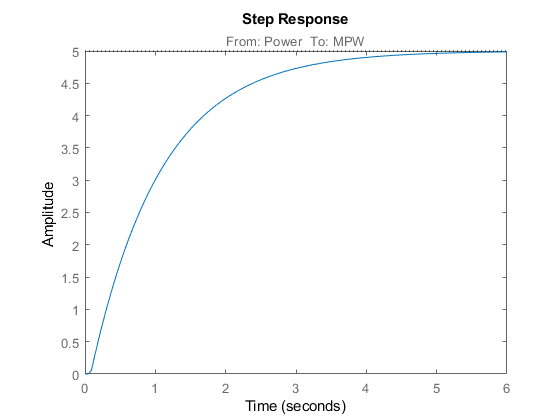

         'InputName',input_name,'InputUnit',input_unit, 'OutputName', output_name,...
         'OutputUnit', output_unit)
%--------------------convert directly from the linear model
%G1 = idtf(midproc) % plant model

`plot step response of open loop transfer function of plant`

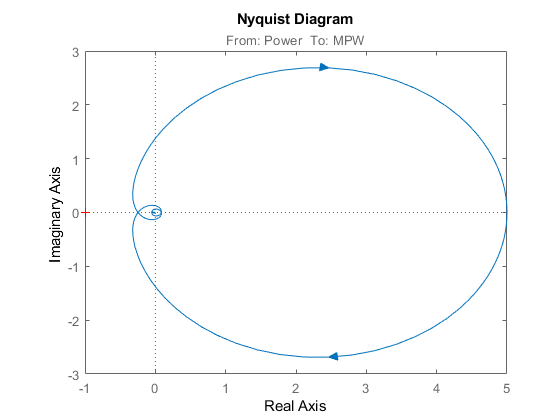

step(G1)

`for this open-loop system:`

`bode plot and nyquist digram to examine the crossover frequency`

nyquist(G1)

Gm = 4.0549

Pm = 79.0817

Wcg = 20.2501

Wcp = 4.8990

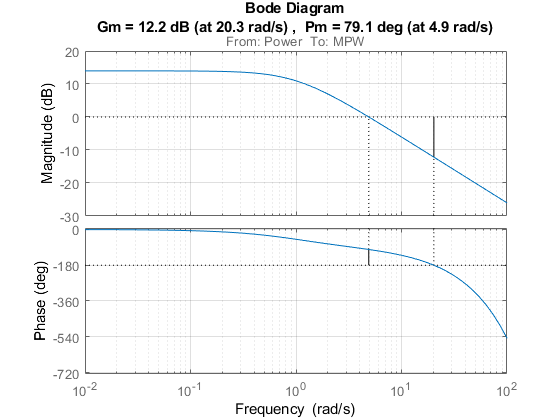


[Gm,Pm,Wcg,Wcp] = margin(G1)


figure % plot the bode and margin in the same graph
%bode(G1)

margin(G1)% calculate margins: Gain margin, phase margin, and crossover frequencies
grid on

### **2. Automatic tuning: PI and PID controller**

** -- balance between reference tracking and disturbance rejection**

`sys = `[zpk](https://www.mathworks.com/help/control/ref/zpk.html)`(Z,P,K) `creates a continuous-time zero-pole-gain model with zeros `Z`, poles `P`, and gain(s) `K`. The output `sys` is a `zpk` model object storing the model data.

`zsys = zpk(sys)`, or `zsys = zpk(sys, 'measured')` converts the measured component of an identified linear model into the ZPK form. `sys` is a model of type `idss`, `idproc`, `idtf`, `idpoly`, or `idgrey`. `zsys` represents the relationship between `u` and `y`.

%sys = zpk([],[-1 -1 -1],1); 
%G1 = zpk(midproc)


C_pid =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.304, Ki = 0.486
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.7810
           PhaseMargin: 69.2763


[C_pid, info] = pidtune (G1, 'PID')


C_pi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.256, Ki = 0.567
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.7810
           PhaseMargin: 60.0000


[C_pi,info] = pidtune(G1,'PI')

`C_pi` is a `pid` controller object that represents a PI controller. The fields of `info` show that the** tuning algorithm chooses an open-loop crossover frequency automatically, which is based on the balance of reference tracking and distrubance rejection.**

**Examine the *****step-reference***** tracking and *****step-disturbance rejection*** of the control system using the default controller. The *disturbance response from d to y i*s equivalent to the response of a closed loop given by `feedback(G1,C_pi)`.

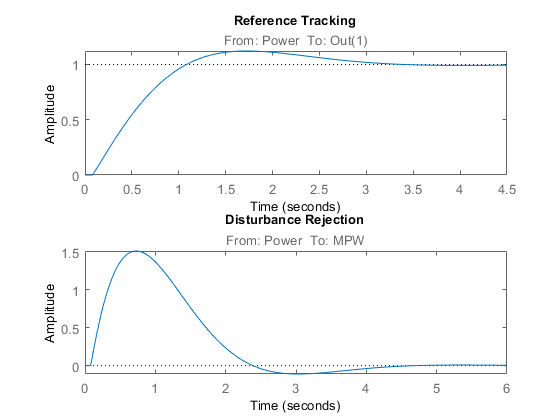

T_pi = feedback(C_pi*G1, 1);
GS_pi = feedback(G1,C_pi);

subplot(2,1,1);
stepplot(T_pi) % plot for step response of close loop system
title('Reference Tracking')

subplot(2,1,2);
stepplot(GS_pi) % plot for step-disturbance rejection of the close loop system
title('Disturbance Rejection')

By default, for a given bandwidth, `pidtune` tunes the controller to achieve a balance between reference tracking and disturbance rejection. In this case, the controller yields some overshoot in the reference-tracking response. The controller also suppresses the input disturbance with a somewhat longer settling time than the reference tracking, after an initial peak. 

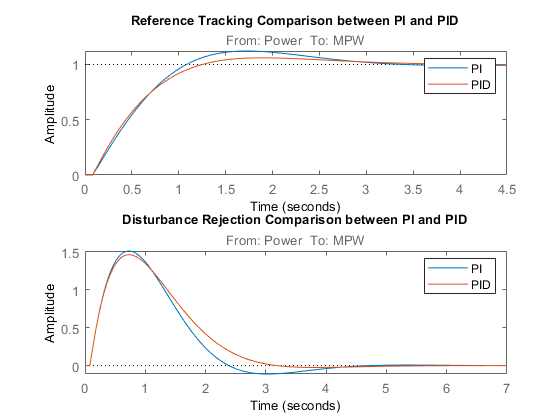

% compare the step reponse of the close loop system with P/PI control
T_pid = feedback (G1*C_pid, 1); % unity feedback Close Loop transfer function
GS_pid = feedback(G1,C_pid); % disturbance transfer function

figure 
subplot(2,1,1);
stepplot (T_pi, T_pid) % plot for step response of close loop system
legend('PI','PID')
title('Reference Tracking Comparison between PI and PID')

subplot(2,1,2);
stepplot(GS_pi, GS_pid) % plot for step-disturbance rejection of the close loop system
legend('PI','PID')
title('Disturbance Rejection Comparison between PI and PID')

It can be seen that PID controller shows slightly better perfomance than PI controller in the balanced tuning condition

--> lower overshoot and better stability

but in general the transient behavior is the same.

Examine the bode plots, phase margin and nyquist crossover frequencies, for the Open loop with PI controller system

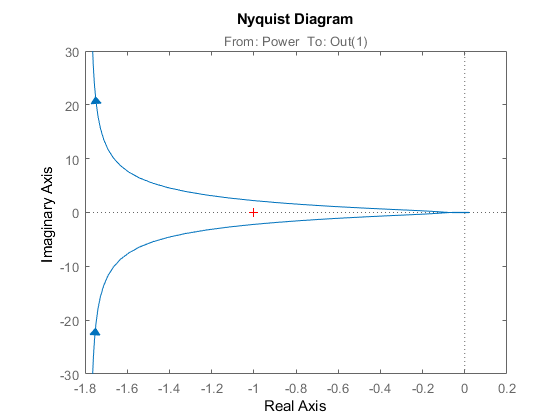

figure
nyquist(C_pi*G1)

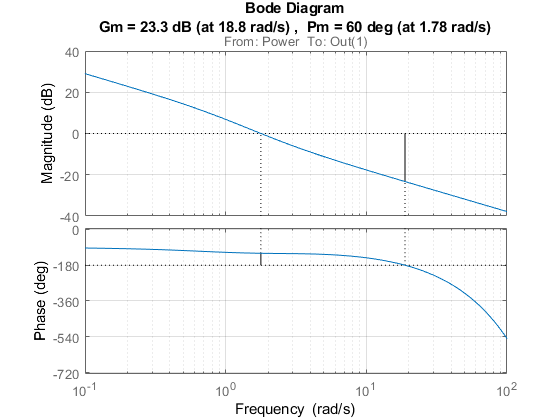


figure % plot the bode and margin in the same graph
%bode(C_pi*G1)
margin(C_pi*G1)
grid on

[Gm,Pm,Wcg,Wcp] = margin(C_pi*G1) % Gain Margin, Phase margin, gain crossoverfrequnecy, phase crossoverfrequency

Gm = 14.6222

Pm = 59.9995

Wcg = 18.8371

Wcp = 1.7812

### 3. Set Target crossover frequnecy(bandwidth) to improve response time or system stability 

Depending on your application, you might want to **alter the balance** between reference tracking and disturbance rejection to favor one or the other. 

For a PI controller, you can alter this balance by changing the target crossover of the tuned system. 

**To improve the response time (faster response)**, you can set a higher target crossover frequency than the result that `pidtune` automatically selects, . Increase the crossover frequency.

**To improve stablity**, decrease the target crossover frequency

[C_pi_fast,info] = pidtune(G1,'PI', 2.5) % set crossoverfrequency here


C_pi_fast =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.41, Ki = 0.872
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.5000
           PhaseMargin: 60.0000


The new controller achieves the higher crossover frequency, but at the cost of a reduced phase margin.

higher phase margin means the higher stability of system

T_pi_fast = feedback(C_pi_fast*G1,1); 
GS_pi_fast = feedback (G1, C_pi_fast);

Compare the closed-loop step response with the two controllers. 

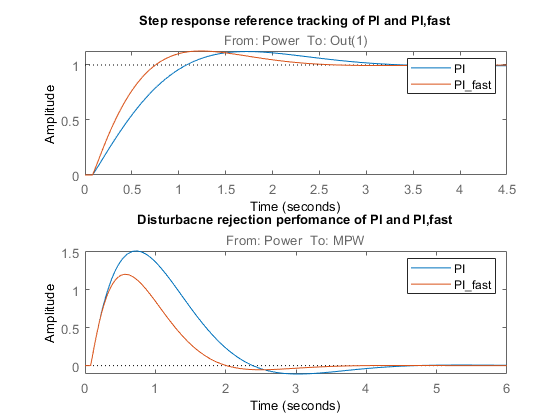

figure
subplot(2,1,1)
step(T_pi,T_pi_fast)
%axis([0 30 0 1.4])
title('Step response reference tracking of PI and PI,fast')
legend('PI','PI_fast')

subplot (2,1,2)
step(GS_pi,GS_pi_fast)
%axis([0 30 0 1.4])
title('Disturbacne rejection perfomance of PI and PI,fast')
legend('PI','PI_fast')

The above plots shows that with increasing the target crossover frequency, the PI controller can make the system response faster and also the faster input disturbance response.

for second order system --> reduction in performance results because the PI controller does not have enough degrees of freedom to achieve a good phase margin at a crossover frequency of 1.0 rad/s. Adding a derivative action improves the response.

**Design a PIDF controller for **`Gc`** with the target crossover frequency of 2.5 rad/s.**

[C_pidf_fast,info] = pidtune(G1,'PIDF',2.5)


C_pidf_fast =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 0.455, Ki = 0.763, Kd = 0.0104, Tf = 0.0733
 
Continuous-time PIDF controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.5000
           PhaseMargin: 68.9954


The fields of info show that the derivative action in the controller allows the tuning algorithm to design a more aggressive controller that achieves the target crossover frequency with a good phase margin.

Compare the closed-loop step response and disturbance rejection for the fast PI and PIDF controllers.

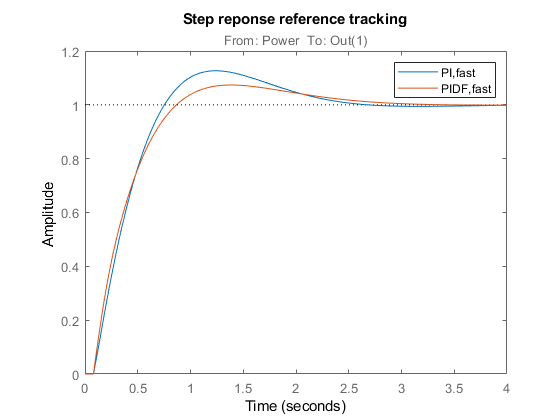

figure
T_pidf_fast =  feedback(C_pidf_fast*G1, 1);
step(T_pi_fast, T_pidf_fast);
%axis([0 30 0 1.4]);
title('Step reponse reference tracking')
legend('PI,fast','PIDF,fast');

**Disturbance rejection peformance of controller**

You can compare the input (load) disturbance rejection of the controlled system with the fast PI and PIDF controllers. To do so, plot the response of the closed-loop transfer function from the plant input to the plant output.

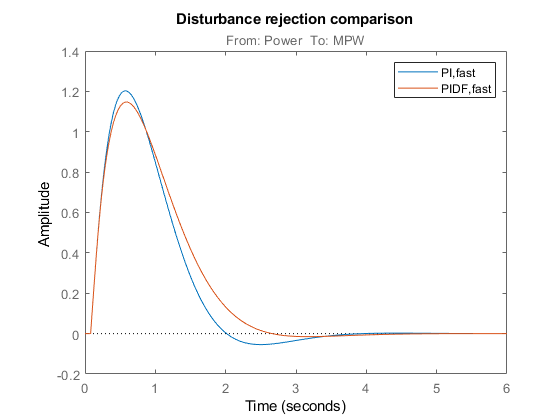

S_pi_fast = feedback(G1,C_pi_fast);
S_pidf_fast = feedback(G1,C_pidf_fast);
step(S_pi_fast,S_pidf_fast);
%axis([0 50 0 0.4]);
title('Disturbance rejection comparison')
legend('PI,fast','PIDF,fast');

This plot shows that the PIDF contr oller also not affect disturbance rejection.

# Tune PID Controller to Favor Reference Tracking or Disturbance Rejection

In the above section, we have obtained and compared three controllers: 

- PI controller tuned automatically without manually setting crossoverfrequency--> default balancing reference tracking and disturbance rejection

- PI controller tuned by setting the crossoverfrequency to achieve a faster responese, but losing some phase margin

- PIDF controller to achieve good phase margin with better disturbance rejection

Alternatively, can tune the PID controller this way: 

### 4. Tune PID controller by setting desired phase margin.

Design controllers for phase margins of 45° and 70° with the same bandwidth(crossover frequency), and compare the resulting reference tracking and disturbance rejection.

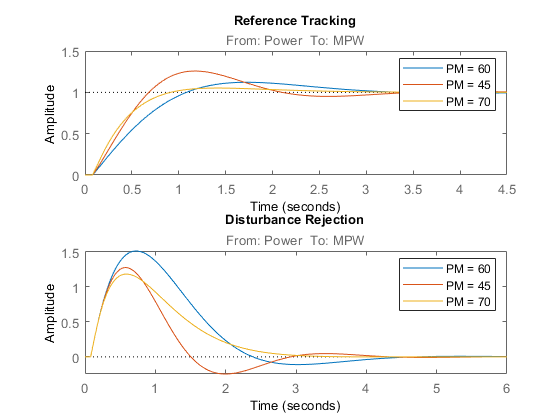

wc = 2.5;
opts2 = pidtuneOptions('PhaseMargin',45);
C_pi2 = pidtune(G1,'PI',wc,opts2);
T_pi2 = feedback(G1*C_pi2,1);
GS_pi2 = feedback(G1,C_pi2);

opts3 = pidtuneOptions('PhaseMargin',70);
C_pi3 = pidtune(G1,'PI',wc,opts3);
T_pi3 = feedback(G1*C_pi3,1);
GS_pi3 = feedback(G1,C_pi3);

subplot(2,1,1);
stepplot(T_pi,T_pi2,T_pi3)
legend('PM = 60','PM = 45','PM = 70')
title('Reference Tracking')
subplot(2,1,2);
stepplot(GS_pi,GS_pi2,GS_pi3)
legend('PM = 60','PM = 45','PM = 70')
title('Disturbance Rejection')

- Lowering the phase margin to 45° speeds up disturbance rejection, but also increases overshoot in the reference tracking response.

- Increasing the phase margin to 70° eliminates the overshoot completely, but results in extremely sluggish disturbance rejection. 

- The effect of the phase margin on this balance depends on the plant model. 

If you want to fix both the bandwidth and phase margin of your control system, you can still change the balance between reference tracking and disturbance rejection using the `DesignFocus` option of `pidtune`. You can set `DesignFocus` to either `'disturbance-rejection'` or `'reference-tracking'` to tune a controller that** favors one or the other.**

The `DesignFocus` option is more effective for a control system with more tunable parameters. Therefore, it does not have much effect when used with a PI controller. To see its effect, design a PIDF controller for the same bandwidth and the default phase margin (60°) using each of the `DesignFocus` values. Compare the results.

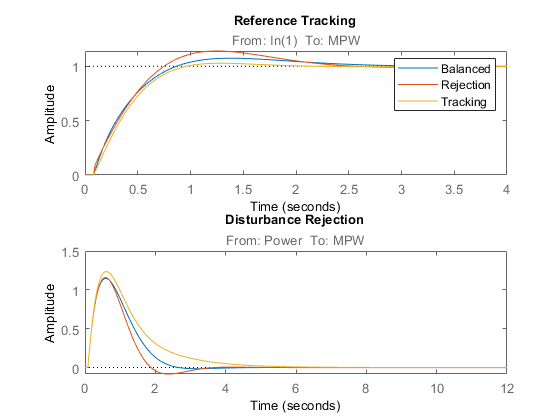

opts4 = pidtuneOptions('DesignFocus','balanced');   % default focus
C4 = pidtune(G1,'PIDF',wc,opts4);
T4 = feedback(G1*C4,1);
GS4 = feedback(G1,C4);

opts5 = pidtuneOptions('DesignFocus','disturbance-rejection');
C5 = pidtune(G1,'PIDF',wc,opts5);
T5 = feedback(G1*C5,1);
GS5 = feedback(G1,C5);

opts6 = pidtuneOptions('DesignFocus','reference-tracking');
C6 = pidtune(G1,'PIDF',wc,opts6);
T6 = feedback(G1*C6,1);
GS6 = feedback(G1,C6);

figure
subplot(2,1,1);
stepplot(T4,T5,T6)
legend('Balanced','Rejection','Tracking')
title('Reference Tracking')
subplot(2,1,2);
stepplot(GS4,GS5,GS6)

title('Disturbance Rejection')

When you use the `DesignFocus` option to favor reference tracking or disturbance rejection in the tuned control system, you can still adjust phase margin for further fine tuning of the balance between these two measures of performance. Use `DesignFocus` and `PhaseMargin` together to achieve the performance balance that best meets your design requirements.

The effect of both options on system performance depends strongly on the properties of your plant. For some plants, changing the `PhaseMargin` or `DesignFocus` options has little or no effect.